# Computing path vectors

## Author: Susan Ghaderi, Systems Biochemistry Group, Luxembourg Centre for Systems Biomedicine 

## Reviewers: Sylvain Arreckx, Laurent Heirendt

## INTRODUCTION

During this tutorial, you will learn how to compute elementary (flux) modes / elementary (flux) vectors and a minimal generating set (convex basis) of flux cones or flux polyhedra associated with mass-flow networks [1].

 To compute elementary modes and convex bases, two different scenarios can be considered: homogeneous and inhomogeneous constraints cases.

-  In homogeneous constraints case, elementary modes are flux vectors with minimal support of the polyhedral cone defined by the steady state assumptions and reversibility constraints. Also, a convex basis is a minimal set of vectors sufficient to generate all flux vectors within the flux cone by non-negative linear combinations of convex basis vectors, which are always a subset of the elementary modes.

- In the other hand in inhomogeneous constraints, elementary modes are a generalization of elementary modes which are all extreme rays, extreme points and representatives of all support-minimal flux patterns or only a minimal set of unbounded (basis of lineality space + extreme rays) and bounded (extreme points) generators spanning the resulting general flux polyhedron [2].

Let $N\in R^{m\times n}$ be a stoichiometric matrix of a metabolic network with $m$ metabolites and $n$ reactions. The steady-state assumption leads to 

                                                                                                       
$$Sv=0  ~~~~~(1)$$


where $v$ is the $n$-dimensional vector of net reaction rates. Each flux vector $v$ satisfying equation (1) is in the nullspace of $S$, having $\text{n-rank(}S\text{)}$.  Irreversible reactions, contained in the set $\Delta$, have sign restrictions on their rates which can be expressed by the inequalities


$$v_i\geq0~\forall i \in \Delta~~~(2)$$


The set  $\Phi$ of flux vectors $v$ satisfying equations (1) and (2) 

                                                                                                        
$$\Phi =\{v\in R^n |Sv=0, ~v_i\geq0 ~\forall ~i\in \Delta\}~~~(3)$$


is a subset of the nullspace of $S$, which is called convex polyhedral cone or flux cone. Elementary modes are defined as the nonzero, support-minimal vectors of the flux cone. If every reaction is irreversible then elementary modes are called extreme pathways. In general extreme pathways are a subset of elementary modes. In graphical point of view, elementary modes and extreme pathways are continuous paths. 

We introduce an interface to software that enables the computation of the elementary modes, or extreme pathways, given a network and user-defined reaction bounds.

## MATERIALS

- *Please ensure that the COBRA Toolbox has been properly installed and initialised. *

- *Also, you should install CNA (CellNetAnalyzer) software and initialise it. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

*Before you start with these codes, you should initialise The COBRA Toolbox and CNA software by the following commands*

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

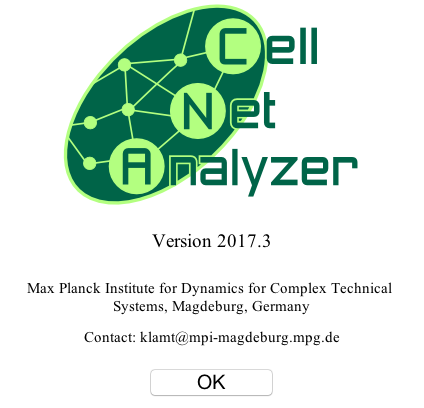

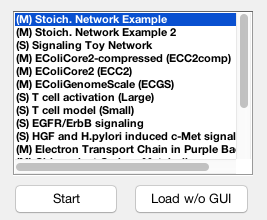

% Add path to Cell Net Analyzer
CNAPath = '~/CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna

## Elementary modes and extreme pathways

The mandatory inputs for computing elementary modes and extreme pathways are a model that user are going to compute its path vectors (elementary modes or extreme pathways (convex basis)) and a directory that CNA model is going to be saved there. A model should be a COBRA model, a simple MATLAB `struct` with fields defined in the [Documentation](https://opencobra.github.io/cobratoolbox/docs/COBRAModelFields.html). 

% define the model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'pathVectors'])
load('smallmodel.mat')
% define the directory (the place that CNA model will % be saved there)
directory = 'Pathwaysvector';
[E, id, ir, rev, modelOut] = pathVectors(smallmodel, directory)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

E =     -1     0
     1     0
     0     1
     0    -1
    -1    -1


id =      2
     3
     4
     5
     6


ir =      1
     1


rev =      1     1


modelOut =     description: 'COBRA model converted from a CNA project'
           rxns: {6×1 cell}
           mets: {15×1 cell}
              S: [15×6 double]
             lb: [6×1 double]
             ub: [6×1 double]
            rev: [6×1 double]
              c: [6×1 double]
       rxnNames: {6×1 cell}
       metNames: {15×1 cell}
              b: [15×1 double]


## Optional inputs

The function can have some optional inputs which depend on computing elementary modes or extreme pathways. We explain the most important optional inputs in the following. 

- `constraints`: is a matrix specifying homogeneous `0` and inhomogeneous `1` constraints on the reaction rates; 

- `mexVe``rsion`: there are four options for mexversion, that the default value is `4`.

                       - `1`:  use CNA mex files,

                       - `2`: use Metatool mex files,

                       - `3`: use both CNA and Metatool mex files  

                       - `4`: use Marco Terzer's EFM tool (see http://www.csb.ethz.ch/tools/index)

- `irrevFlag` : if set to `0,` considers the reversibility of reactions and set to `1` if it does not consider reversibility.

- `convbasisFlag`: if set to `0`, all elementary modes/vectors are calculated and if set to `1`, only a minimal generating set (convex basis) is calculated (default: `0`).

- `isoFlag` : consider isoenzymes (parallel reactions) only once or not; the default value is (default: `0`).

- `cMacro`: vector containing the concentrations (g/gDW) of the macromolecules if a variable biomass composition has been defined (cnap.mue not empty). Can be empty when cnap.mue or cnap.macroComposition is empty. If it is empty and cnap.mue is not empty then cnap.macroDefault is used. In CNA models default is cnap.macroDefault, but in COBRA models if it is not contain mu (biomass composition) then the default value is empty.

- `display`: control the detail of console output; the default value is '`None`'. Other options are `'Iteration'`, `'All'` or `'Details'`.

- `positivity`: whether a non-negative convex basis  `1` or not `0`. If yes it converts every reversible reaction to two irreversible reactions. 

For a complete list of optional inputs and their definition, you can run the following command.

help pathVectors

  Computes elementary mode and extreme pathway
  (convex basis) of a COBRA model using the CellNetAnalyzer software
  package [1].
 
  CellNetAnalyzer can be downloaded at https://www2.mpi-magdeburg.mpg.de/projects/cna/download.html
 
  INPUTS:
     model:             COBRA model
 
                          * S  - `m x 1` Stoichiometric matrix
                          * c  - `n x 1` Linear objective coefficients
                          * lb - `n x 1` Lower bounds
                          * ub - `n x 1` Upper bounds
 
     directory:         folder path to where the CNA model is going to be 
                        saved (required for intermediate computations)
 
  OPTIONAL INPUTS:
     constraints:       empty
                        the number of reactions
                        many rows and up to 4 columns:
                        - COLUMN1 specifies excluded/enforced reactions: if
           

The following function compute a convex basis for the model by the name smallmodel which its CNA version will be saved in the `directory` address.

[E, id, ir, rev, modelOut] = pathVectors(smallmodel, directory,'convBasisFlag',1)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

E =     -1     0
     1     0
     0     1
     0    -1
    -1    -1


id =      2
     3
     4
     5
     6


ir =      1
     1


rev =      1     1


modelOut =     description: 'COBRA model converted from a CNA project'
           rxns: {6×1 cell}
           mets: {15×1 cell}
              S: [15×6 double]
             lb: [6×1 double]
             ub: [6×1 double]
            rev: [6×1 double]
              c: [6×1 double]
       rxnNames: {6×1 cell}
       metNames: {15×1 cell}
              b: [15×1 double]


## Output

The output of `pathVectors.m is`

-  `E `:  the matrix that contains (row-wise) the elementary modes (or elementary vectors) or a minimal set of generators (lineality space + extreme rays/points), depending on the chosen scenario. The columns  correspond to the reactions; the column indices of efms (with respect to the columns in cnap.stoichMat) are stored in the returned  variable idx (see below; note that columns are removed in efms if the corresponding reactions are not contained in any mode)

-  `rev`  :    vector indicating for each mode whether it is reversible(0)/irreversible (1)

-  `id `:    maps the columns in efm onto the column indices in cnap.stoichmat, i.e. idx(i) refers to the column number in cnap.stoichmat (and to the row number in cnap.reacID)

- `ir `:    indicates whether the i-th row (vector) in efm is an unbounded (1) or bounded (0) direction of the flux cone / flux polyhedron. Bounded directions (such as extreme points) can only arise if an inhomogeneous problem was defined.

To clarify above description for example, if you look at the output `E` is 

E

E =     -1     0
     1     0
     0     1
     0    -1
    -1    -1


and 

id

id =      2
     3
     4
     5
     6


That means reactions 2, 3, 4 ,5 and 6 participate in the elementary modes. For example, reactions 2, 3 and 6 are made elementary mode one in `E(1), `which in every elementary mode two of reaction use reversible reactions.

## TIMING

Running, the codes are dependent on the size of models may take long from 30 seconds to few hours. But in addition to the time of running you should allow 60 seconds to start-up the CNA software.

## ANTICIPATED RESULTS

If the user just wants to compute extreme pathways that all the elements be non-negative should use the following parameters

[E, id, ir, rev, modelOut] = pathVectors(smallmodel, directory, 'convBasisFlag', 1, 'irrevFlag', 1, 'positivity', 1)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 10.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Sav

E =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     1     0     0     0     0     0
     0     1     1     0     0     0
     0     0     0     1     1     0
     0     0     1     1     0     1


id =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ir =      1
     1
     1
     1
     1
     1


rev =      1     1     1     1     1     1


modelOut =     description: 'COBRA model converted from a CNA project'
           rxns: {10×1 cell}
           mets: {15×1 cell}
              S: [15×10 double]
             lb: [10×1 double]
             ub: [10×1 double]
            rev: [10×1 double]
              c: [10×1 double]
       rxnNames: {10×1 cell}
       metNames: {15×1 cell}
              b: [15×1 double]


[E, id, ir, rev, modelOut] = pathVectors(smallmodel, directory, 'convBasisFlag', 1, 'irrevFlag', 1)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

E =     -1     0
     1     0
     0     1
     0    -1
    -1    -1


id =      2
     3
     4
     5
     6


ir =      1
     1


rev =      1     1


modelOut =     description: 'COBRA model converted from a CNA project'
           rxns: {6×1 cell}
           mets: {15×1 cell}
              S: [15×6 double]
             lb: [6×1 double]
             ub: [6×1 double]
            rev: [6×1 double]
              c: [6×1 double]
       rxnNames: {6×1 cell}
       metNames: {15×1 cell}
              b: [15×1 double]


If the user wants to compute elementary modes, that is enough to just put `c``onvBa``sisFlag = 0,` and for checking other variables like reversibility and ... is optional.

[E, id, ir, rev, modelOut] = pathVectors(smallmodel, directory, 'convBasisFlag', 0)

Field 'type' not defined. Initialized with '1' (for mass-flow).
Field 'nums' not defined. Initialized with 15.
Field 'numr' not defined. Initialized with 6.
Field 'specNotes' not defined. Initialized empty 'specNotes'.
Field 'specExternal' not defined. Initialized with zero vector (i.e. all species are configured as internal).
Field 'reacNotes' not defined. Initialized empty 'reacNotes'.
Field 'reacVariance' not defined. Initialized for all reactions a variance level of 0.01.
Field 'reacDefault' not defined. Initialized with NaN vector (empty default values).
Field 'mue' not defined. Initialized according to existence of string 'mue' in 'reacID'.
Field 'reacBoxes' not defined. Initialized with default values.
Field 'macroComposition' not defined. Initialized as empty matrix (no macromolecules defined; other fields related to macromolecules adapted/initialized accordingly).
Field 'epsilon' not defined. Initialized with '1e-10'.
Field 'has_gui' not defined. Initialized with 'false'.
Savi

E =     -1     0
     1     0
     0     1
     0    -1
    -1    -1


id =      2
     3
     4
     5
     6


ir =      1
     1


rev =      1     1


modelOut =     description: 'COBRA model converted from a CNA project'
           rxns: {6×1 cell}
           mets: {15×1 cell}
              S: [15×6 double]
             lb: [6×1 double]
             ub: [6×1 double]
            rev: [6×1 double]
              c: [6×1 double]
       rxnNames: {6×1 cell}
       metNames: {15×1 cell}
              b: [15×1 double]


## *TROUBLESHOOTING*

*To compute elementary modes, you should ****not ****use the *`mexVersion 2`*, because of this option just it is for computing convex basis and you will get this comment.*

`Undefined function or variable 'to_bits_c'.`

`Error in elmodes_calc`

`Error in compute_elmodes`

## REFERENCES

[1] Klamt, S. et al.  Algorithmic approaches for computing elementary modes in large biochemical reaction networks. IEE Proc. Syst. Biol., 152, 249–255 (2005).

[2] Kamp. A. and Klamt S. Enumeration of smallest intervention strategies in genome-scale metabolic networks. PLoS Computational Biology, 10:e1003378. (2014).